# **Example script**

This script is used to evaluate the ensemble ml model on an external test set. 

The ensemble Ml model is trained using the 11 selected features.

1)* "wavelet_LHH_firstorder_Skewness"*, 

2) *"wavelet_HHL_glszm_SmallAreaEmphasis"*, 

3) *"wavelet_LHL_gldm_DependenceVariance"*, 

4) *"wavelet_HHL_glszm_SmallAreaLowGrayLevelEmphasis"*,

5) *"log_sigma_0_5_mm_3D_ngtdm_Busyness"*,

6) *"log_sigma_2_5_mm_3D_glszm_GrayLevelNonUniformity"*, 

7) *"wavelet_HHL_gldm_SmallDependenceLowGrayLevelEmphasis"*, 

8) *"wavelet_HLH_glszm_GrayLevelNonUniformity"*, 

9) *"wavelet_HLH_glcm_Idn"*,

10) *"wavelet_HHL_glcm_Idn"*, 

11) *"log_sigma_4_0_mm_3D_firstorder_Skewness"*

In the default settings, **the external test set corresponds to the dataset used to train the model. Therefore, the performance are resubmission performance**.

The variable *"file_testset"* represents the external test set. The file **must be organised** as follows. 

The first column corresponds to the patient names, while the last column to the labels. Labels must be "high risk" for high risk patients and "low risk" for low risk patients.

%Copyright 2024, Giovanni Pasini, Department of Mechanical and
%Aerospace Engineering (DIMA), University of Rome La Sapienza|
%Institute of Bioimaging and Molecular Physiology, National Research
%Council (IBFM-CNR)

clear variables
close all
clc

addpath("ensemble_ML_model")
addpath('external_testset')

%import dataset
folder = 'external_testset'; %folder that contains the external test set
file_testset = 'dataset.xlsx'; %change file to change test set
testset = readtable([folder,'/',file_testset]);

Continuing with testing....
    accuracy     auc      sensitivity    specificity    precision    fscore 
    ________    ______    ___________    ___________    _________    _______

    0.83217     0.8973      0.81944        0.84507       0.84286     0.83099



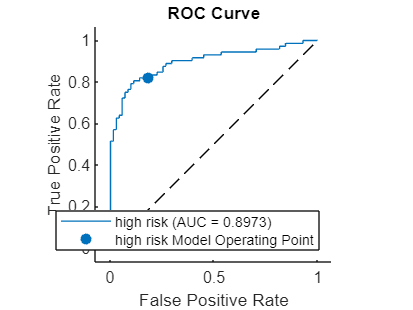

    observation    risk prediction    probability
    ___________    _______________    ___________

    "ANON21010"      "low risk"        "0.85287" 
    "ANON25631"      "low risk"        "0.47641" 
    "ANON22708"      "low risk"        "0.91447" 
    "ANON19411"      "high risk"       "0.74975" 
    "ANON90386"      "low risk"        "0.74632" 
    "ANON13412"      "low risk"        "0.54107" 
    "ANON84994"      "low risk"        "0.81928" 
    "ANON58790"      "low risk"        "0.68822" 
    "ANON99157"      "low risk"        "0.87155" 
    "ANON67523"      "low risk"        "0.91006" 
    "ANON35134"      "low risk"        "0.86129" 
    "ANON63662"      "low risk"        "0.83138" 
    "ANON64154"      "low risk"        "0.84424" 
    "ANON42020"      "low risk"        "0.8124"  
    "ANON13910"      "low risk"        "0.79872" 
    "ANON55630"      "low risk"        "0.62534

%

%Create model Instace
model = ensembleModel();

%Evaluate model on the external test set
[performance, roc, predictions] = model.evaluateModel(testset);